For use with large stitched *.h5 images with two channels containing Pcad and Sox9 stains

A. In Fiji: 1) Duplicate these two channels, with ch0=Pcad and ch1=Sox9, 2) Generate an Average Z-projection of your chosen z-planes, 3) Save as: h5 (new or replace). Popup screen will show "Dataset names template", make sure these match the format /t{t}/channel{c} 

Alt: Use the 'convert2h5.m' script to automatically convert batches of images to the .h5 format

B. Adjust values and preferences below. In most cases, adjusting the 'threshold' and 'mean intensity threshold' values is sufficient. In case of differences in resolution, the size and length variables may need to be adjusted accordingly. 

Dependencies: 

François Beauducel (2021). ARROWS: generalized and vectorized 2-D arrows plot (https://www.mathworks.com/matlabcentral/fileexchange/37371-arrows-generalized-and-vectorized-2-d-arrows-plot), MATLAB Central File Exchange. Retrieved January 5, 2021.

% % Load images 
cd(userpath)
[file, path] = uigetfile('Images/Maureen/*.h5');
addpath(path);
% rotate and flip image data to match original orientation
imPcad = flip(imrotate(h5read(file, '/t0/channel0'), 90),1);
imSox9 = flip(imrotate(h5read(file, '/t0/channel1'), 90),1); 

 

saveflag = true;

Pcad segmentation

threshRatioP   = 0.3; 
threshMeanIntP = 0.2;
sizemaxP = 2500;
sizeminP = 300;
[bwPcad, XPcad] = segmentPcad(imPcad, threshRatioP, threshMeanIntP, sizemaxP, sizeminP);

Sox9 segmentation

% Sox9 segmentation
threshRatioS   = 0.3;
threshMeanIntS = 0.2;
sizemaxS = 2500;
sizeminS = 400;
[bwSox9, XSox9] = segmentSox9(imSox9, threshRatioS, threshMeanIntS, sizemaxS, sizeminS);

Identify downgrown and polarized follicles. Downgrowth identified by "donut" shape where a slightly expanded region of either Pcad or Sox9 can fully contain the other, leaving a hole when subtracted. Polarized follicles identified by non-overlapping regions of sufficient size. 

BWindex = (bwPcad+bwSox9)>0;
numobjects = bwconncomp(BWindex).NumObjects;
% % 2. Identify down-grown follicles using Euler number (may include some
% slightly polarized; need some global assignment to pref one or the other)
dilateS =6;
dilateP =8;
outerSox9 = (imdilate(bwSox9,  [strel('line',dilateS,90), strel('line',dilateS,0)]) - bwPcad)>0;
ringSox9 = bwpropfilt(outerSox9, 'EulerNumber', [-3 0]);
outerPcad = (imdilate(bwPcad, [strel('line',dilateP,90), strel('line',dilateP,0)]) - bwSox9)>0;
ringPcad = bwpropfilt(outerPcad, 'EulerNumber', [-3 0]);
%donuts = bwpropfilt(ringSox9, uint16(ringPcad), 'meanintensity', [0.0001 1]);
donuts = ringPcad & ringSox9;
pdown = vertcat(regionprops(donuts, 'Centroid').Centroid)';
numdown = size(pdown,2);

% 3. Identify polarized follicles and calculate angle
% Remove overlapping regions to leave only non-overlapping edges
edgePcad = (bwPcad - bwSox9)>0;
edgeSox9 = (bwSox9 - bwPcad)>0;
% Remove small remaining regions (noise)
minEdgeSize = 30;
edgePcad2 = bwareaopen(edgePcad, minEdgeSize);
edgeSox92 = bwareaopen(edgeSox9, minEdgeSize);
% Find weighted centroid using non-overlapping regions as the weight
propsPcad = regionprops(bwPcad, edgePcad2, 'WeightedCentroid');
propsSox9 = regionprops(bwSox9, edgeSox92, 'WeightedCentroid');
wcPcad = vertcat(propsPcad.WeightedCentroid)';
wcSox9 = vertcat(propsSox9.WeightedCentroid)';
% Create "cost" matrix of region pairs
distanceMat = zeros(size(wcSox9,2),size(wcPcad,2));
for k = 1:size(wcSox9,2)
  distanceMat(k,:) = vecnorm([wcSox9(1, k)-wcPcad(1,:); 
      wcSox9(2, k)-wcPcad(2,:)],2,1)';  % calculate norm by columns
end
minDistance = 15;
% Set maximum distance between two objects in a pair by setting larger
% distances (and NaNs) to infinity
maxDistance = 40;
for i=1:size(distanceMat,1)
    for j=1:size(distanceMat,2)
        if distanceMat(i,j)>maxDistance || isnan(distanceMat(i,j))
            distanceMat(i,j) = Inf; 
        end 
    end
end
% Run assignment algorithm
costUnassign = maxDistance;
[Pairs, uR, uC] = matchpairs(distanceMat, costUnassign); % in 'Pairs' column1 is Sox9, c2 is Pcad
numpolar = size(Pairs,1);
numplacode = size(uR,1)+size(uC,1);
polarCoords = wcPcad(:, Pairs(:,2))';                    % record x,y coordinates of the Pcad centroid

Output

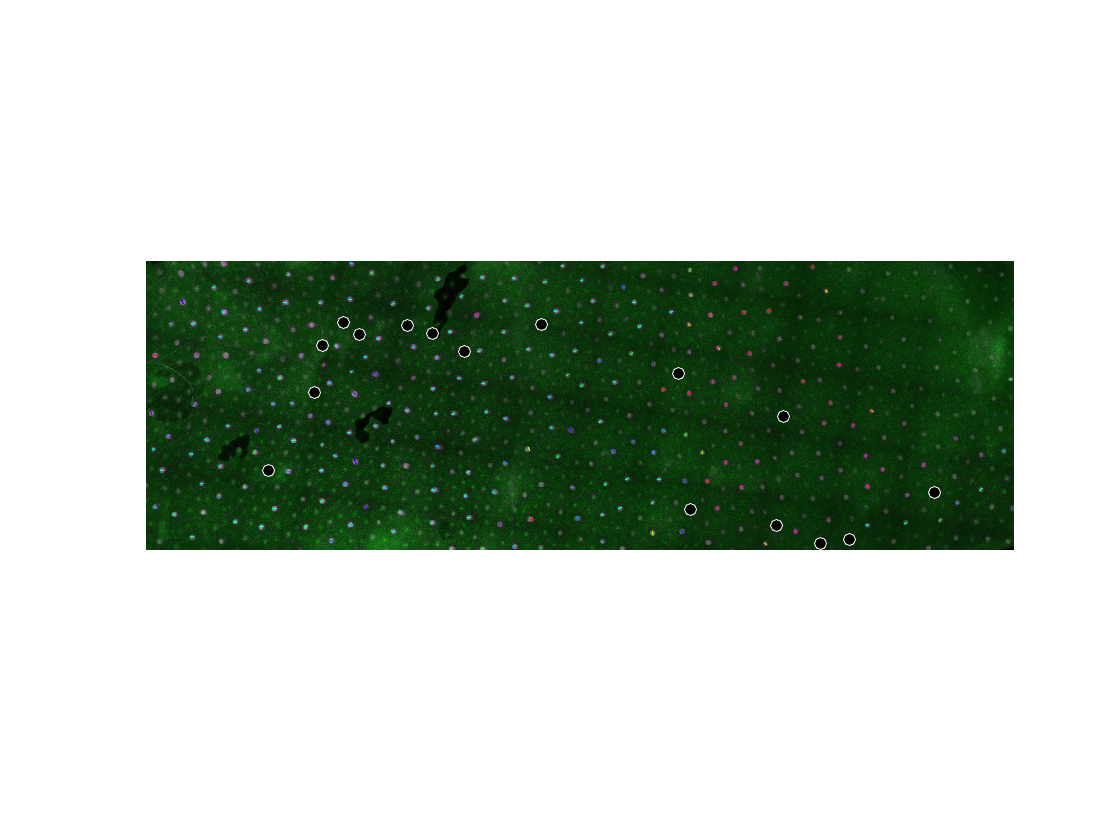

bwpolar = bwlabel(bwselect(BWindex, polarCoords(:,1), polarCoords(:,2)));          % index polar follicles
bwdown = bwlabel(bwselect(BWindex, pdown(1,:), pdown(2,:)));                       % index downgrown follicles
% create follicle data:
% Every object found in either Pcad and Sox9 is accounted for and labeled downgrown, angled, or neither, 
% and associated values stored as well. 0 = neither/early, 1 = angled, 2 = down
% x-cord    y-cord  label(0-2)  angle(0:360)    angle(-180:180)   distance    color(R)    color(G)    color(B) 
varNames = {'xCord', 'yCord', 'label', 'angle(0:360)', 'angle(-180:180)', 'distance', 'colorR', 'colorG', 'colorB'};
follicleData = table('Size', [numobjects, 9], 'VariableTypes', string(repmat('double', 9,1)), 'VariableNames', varNames);

c = regionprops(BWindex, 'Centroid');
c = vertcat(c.Centroid);
follicleData(:,1) = table(c(:,1));
follicleData(:,2) = table(c(:,2));
% draw image overlayed with arrows to double-check accuracy
figure; imshow(imfuse(imPcad, imSox9));
hold on
for j=1:numobjects
    % if there is an object in bwpolar at these coordinates, treat as polarized
    if sum(sum(bwselect(bwpolar, follicleData{j,1}, follicleData{j,2})))>0    
        n = bwpolar(round(follicleData{j,2}), round(follicleData{j,1}));      % extract index for angle data
        % gather values of x and y for each centroid
        x1 = wcSox9(1, Pairs(n,1));
        y1 = wcSox9(2, Pairs(n,1));
        x2 = wcPcad(1, Pairs(n,2));
        y2 = wcPcad(2, Pairs(n,2));
        % calculate distance and angle between centroids
        distance = sqrt((x2-x1).^2 + (y2-y1).^2);        % calculate distance
        if distance >= 18                                % if distance is above a threshold, record angle and draw arrows
            rad = atan2((y1-y2),(x1-x2));
            follicleData{j,5} = rad2deg(rad);                  % record -180:180 angle
            if follicleData{j,5}<0                           % reassign -180:0 values to 180:360 range
                follicleData{j,4} = follicleData{j,5}+360;
            else
                follicleData{j,4} = follicleData{j,5};
            end
            % convert angle to color
            hsv = [mod(follicleData{j,4}/360-.5, 1), 1, 1];
            follicleData{j,7:9} = hsv2rgb(hsv);
            follicleData{j,3} = 1;
            follicleData{j,6} = distance;
            arrows(x1, y1, follicleData{j,6}, -90-(follicleData{j,4}), ...
                'FaceColor', follicleData{j,7:9}, 'EdgeColor', follicleData{j,7:9});     % Draw arrows
        else
            follicleData{j, 4:6} = NaN;                 % if below threshold, record as non-polar and check if downgrown
             if sum(sum(bwselect(bwdown, follicleData{j,1}, follicleData{j,2})))>0
                 follicleData{j,3} = 2;
                 plot(follicleData{j,1}, follicleData{j,2}, 'o', 'MarkerEdgeColor', 'w', 'MarkerFaceColor','k');
             else
                 follicleData{j,3} = 0;
             end
        end
    % else, if there is an object in bwdown at these coordinates, treat as downgrown  
    elseif sum(sum(bwselect(bwdown, follicleData{j,1}, follicleData{j,2})))>0
        follicleData{j,3} = 2;
        follicleData{j,4:6} = NaN;
        plot(follicleData{j,1}, follicleData{j,2}, 'o', 'MarkerEdgeColor', 'w', 'MarkerFaceColor','k');
    % else, if neither polar or downgrown, count as neither (early stage or unclear phenotype)
    else 
        follicleData{j,3} = 0;
        follicleData{j,4:6} = NaN;
    end
end
hold off

follicleData{j+1, 1:2} = [size(BWindex, 2), size(BWindex, 1)];      % store size of original image as [x y] coordinate of the bottom right corner
follicleData{j+1, 3:9} = NaN;                                       % fill remaining values with NaN
[msgStr,warnId] = lastwarn;
warnStruct = warning('off',warnId);


Check segmentation (Pcad in green, Sox9 in magenta). If large regions are missing in one channel, decrease the corresponding 'threshRatio' and/or 'threshMeanInt' value. If there are many small objects, increase 'sizemin'. If regions are too large (ie, magenta Sox9 is fully covering most green Pcad regions), increase 'threshRatio' and/or 'threshMeanInt'

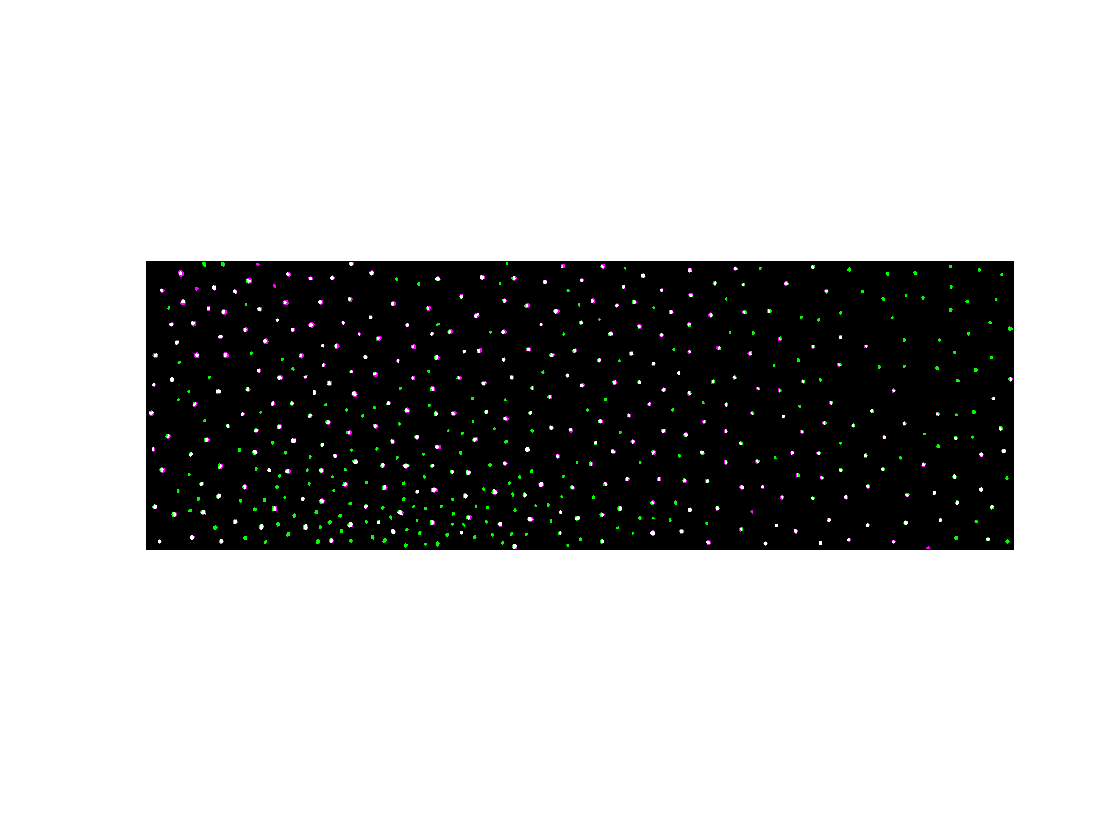

figure; imshow(imfuse(bwPcad, bwSox9))

Check calibration for downgrown identification. Incorrect rings in a given channel may indicate either the segmentation is too permissive, or the dilation is too large; and vice versa. First try increasing the 'threshRatio' and/or 'threshMeanInt' values. If that is not enough, decrease the dilation value.

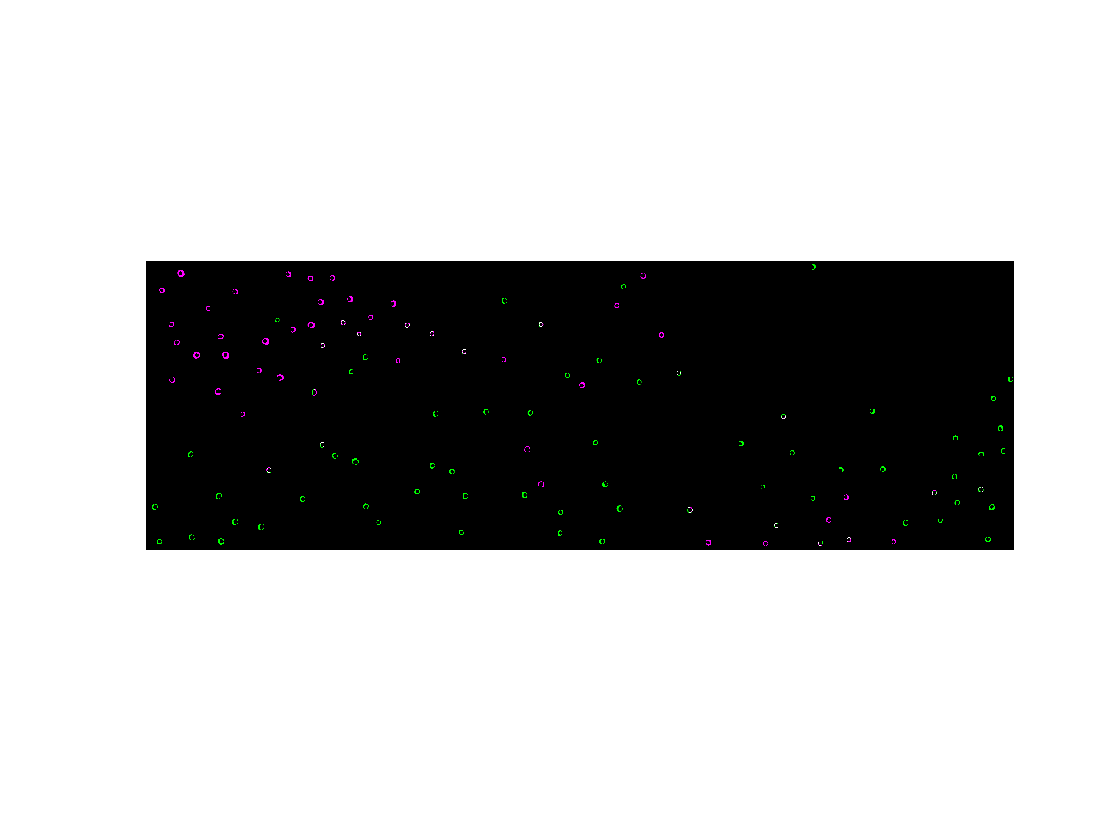

figure; imshow(imfuse(ringPcad, ringSox9))

A-P plot to check overall trends:

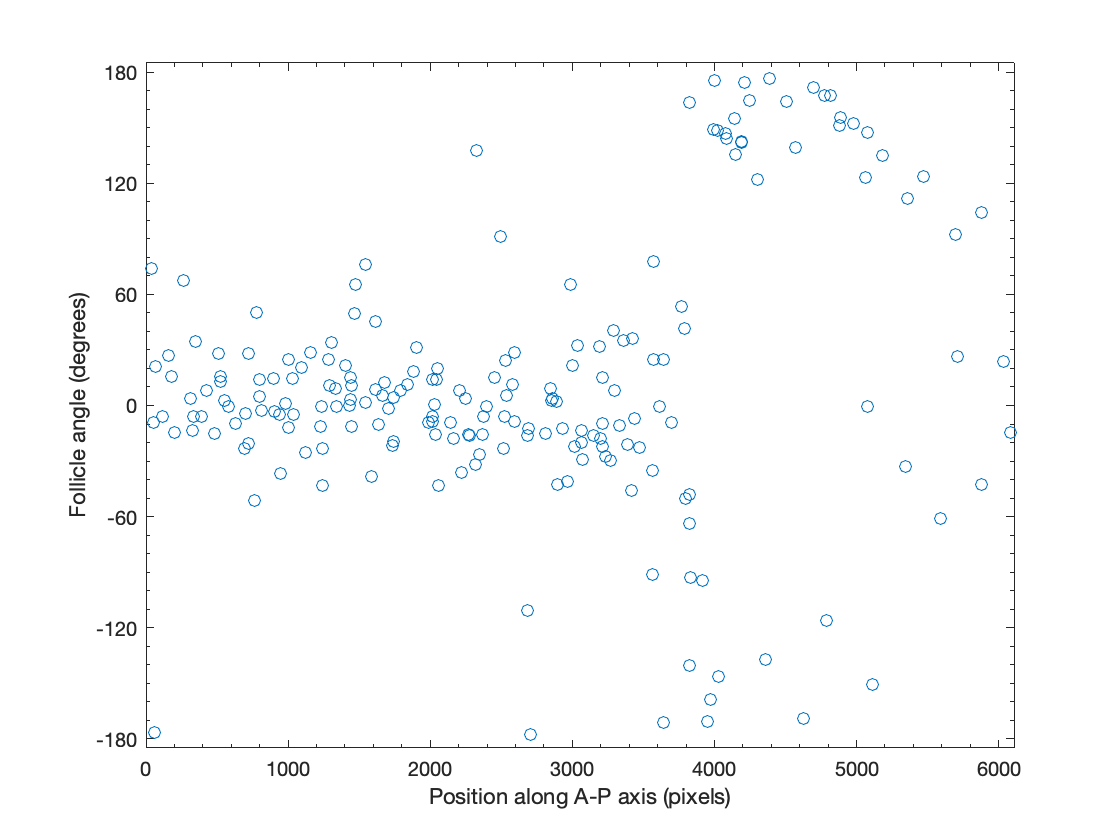

% AP axis vs angle plot
AP = figure;
plot(follicleData{:,1}, follicleData{:,5}, 'o', 'color', '#0072BD')
xlabel('Position along A-P axis (pixels)');
ylabel('Follicle angle (degrees)');
yticks(-180:60:180);
ax = gca;
ax.YLim = [-185 185];
ax.XLim = [0 size(imPcad, 2)];
ax.XMinorTick = true;
ax.YMinorTick = true;



if saveflag == true
    % Save follicleData matrix for image
    save([path, file, ' data', '.mat'], 'follicleData')
end

function [BW, X] = segmentSox9(imSox9, threshRatioS, threshMeanIntS, sizemaxS, sizeminS)
    X = (imSox9-imopen(imSox9, strel('disk', 200)));    
    X = (X-imtophat(X, strel('disk', 2)));    
    X = (imtophat(X, strel('disk', 30)));                 % Adjust image to span data range and equalize background. 
                                                                  % strel('disk', r) where r is bigger than the object radius
    Z = (imopen(X, strel('disk', 3)));                    % Expand dark areas to differentiate dense follicles vs loose placodes
    limit = max(Z, [], 'all');                                    % Find max intensity of the image
    %BW = Z > threshRatioS*limit;                                  % Threshold image to segment
    t = adaptthresh(Z, .001, 'NeighborhoodSize', 101);
    BW=imbinarize(Z, t);
    BW = imclose(BW, strel('disk', 5));
    BW = BW - bwareaopen(BW, sizemaxS);
    iterations = 100;
    contractionbias = 0.4;
    smoothfactor = 2;
    BW = activecontour(X, BW, iterations, 'Chan-Vese', ...
    'ContractionBias', contractionbias, 'SmoothFactor', smoothfactor);  % Expand area to identify follicle edges
    BW = bwpropfilt(BW, X, 'MeanIntensity', [threshMeanIntS*limit, limit]); % Remove faint objects
    BW = BW - bwareaopen(BW, sizemaxS);                          % Removes large noisy objects (anything larger than biggest follicles)
    BW = bwareaopen(BW, sizeminS);                               % Remove objects with area smaller than sizelimit
    BW = imclearborder(BW, 4);
end

function [BW, X] = segmentPcad(imPcad, threshRatioP, threshMeanIntP, sizemaxP, sizeminP)
X = (imtophat(imPcad, strel('disk', 20)));          % Adjust image to span data range and equalize background. 
                                                            % strel('disk', r) where r is bigger than the object radius
Z = (imopen(X, strel('disk', 4)));                  % Expand dark areas to differentiate dense follicles vs loose placodes
limit = max(Z, [], 'all');                                  % Find max intensity of the image                                    
%BW = Z > threshRatioP*limit;                                % Threshold image to segment
t = adaptthresh(Z, .01, 'NeighborhoodSize', 101);
BW = imbinarize(Z, t);
BW = bwpropfilt(BW, Z, 'MeanIntensity', [threshMeanIntP*limit, limit]);% Remove faint objects 
BW = imfill(BW, 'holes'); 
iterations = 100;
contractionbias = -0.05;
smoothfactor = 2;
BW = activecontour(X, BW, iterations, 'Chan-Vese', ...
    'ContractionBias', contractionbias, 'SmoothFactor', smoothfactor);    % Expand area to identify follicle edges
BW = BW - bwareaopen(BW, sizemaxP);                             % Removes large noisy objects (anything larger than biggest follicles)  
BW = bwareaopen(BW, sizeminP);                              % Remove objects with area smaller than sizelimit
BW = imclearborder(BW, 4); 
end